%Constantes del problema
clc;
clear;
close all;

## === Carga Mecanica ===

b_l = 0.1%0.1;  %===> %Coeficiente de friccion viscosa en articulacion (0.1 +/- 0.03) incertidumbre [(N*m)/(rad/s)]

b_l = 0.1000

g = 9.80665; %Aceleracion de gravedad [m/s^2]
m = 1;  %Masa del brazo manipulador [kg]
l_cm = 0.25;    %Longitud equivalente del centro de masa [m]
J_cm = 0.0208;  %Inercia equivalente del centro de masa [kg*m^2]
l_l = 0.5;  %Longitud total (extremo)
m_l = 0;  %===> Masa de carga útil en el extremo (variable de 0 a 1.5) [kg]
J_l = (m*l_cm^2 + J_cm) + m_l*l_l^2;    %Momento de inercia total (a eje de rotacion) [kg*m^2]
k_l = m*g*l_cm + m_l*g*l_l; %Coeficiente de torque recuperador gravitacional


## === Tren de Transmisión ===

r = 120;    %Relacion de trnasmision
nl_nom = 60; %Velocidad nominal (salida) [rpm]
omegal_nom = 6.28; %Velocidad nominal (salida) [rad/s]
Tq_nom = 17;    %Torque nominal (salida) [N*m] (regimen continuo o rms)
Tq_max = 45;    %Torque pico (salida) [N*m] (corta duración, aceleración)

%Modelo equivalente (rígido)
%w_l = (1/r)*w_m

## Parámetros

% Parámetros nominales
J_m = 1.4e-5; % Momento de inercia (kg.m^2)
b_m = 1.5e-5; % Coeficiente de fricción viscosa (N.m/rad/s)
Pp = 3; % Pares de polos magnéticos
lambda = 0.016; % Flujo magnético equivalente de imanes concatenado por espiras del bobinado de estator (Wb-t)
Lq = 5.8e-3; % Inductancia de estator en eje en cuadratura (H)
Ld = 6.6e-3; % Inductancia de estator en eje directo (H)
Lls = 0.8e-3; % Inductancia de dispersión de estator (H)
Rs_ref = 1.02; % Resistencia de estator por fase a 40°C (Ohm)
alpha_Cu = 3.9e-3; % Coeficiente de aumento de Rs con la temperatura (1/°C)
Cts = 0.818; % Capacitancia térmica de estator (W/°C/s)
Rts = 146.7; % Resistencia térmica estator-ambiente (°C/W)
tau_ts_amb = Rts * Cts; % Constante de tiempo térmica estator-ambiente (s)


% Especificaciones de operación
nm_nom = 6600; % Velocidad nominal del rotor (rpm)
omegam_nom = 691.15; % Velocidad nominal del rotor (rad/s)
Vsl_nom = 24; % Tensión nominal de línea (Vrms)
Vs_phase_nom = Vsl_nom / sqrt(3); % Tensión nominal de fase (Vrms)
Is_nom = 0.4; % Corriente nominal (A)
Is_max = 2.0; % Corriente máxima (A)
T_max = 115; % Temperatura máxima del bobinado estator (°C)


## Equivalencias

J_eq = J_m + (1/(r^2))*J_l;
b_eq = b_m + (1/(r^2))*b_l;

## Guardado de constantes

% ruta = 'C:\Users\tobip\Documents\Ayme\Matlab';
% nombre_archivo = 'datos.mat';
% save(fullfile(ruta, nombre_archivo));
% disp('Datos guardados correctamente')

## INPUTS

Valores de amplitudes

% valor_vqs = 20;
% ti_vqs = 0.2;
% tf_vqs = 0.8;
% delta_t = 0.1;
% tf = 1;
valor_T_amb = 0;
valor_Ts_ref = 40;
valor_Tp = 0; %===> Torque de perturbacion externo (funcion escalon de 0 +/- 5) [N*m]
t = [0:delta_t:tf];


valor_Ts_ref = 40

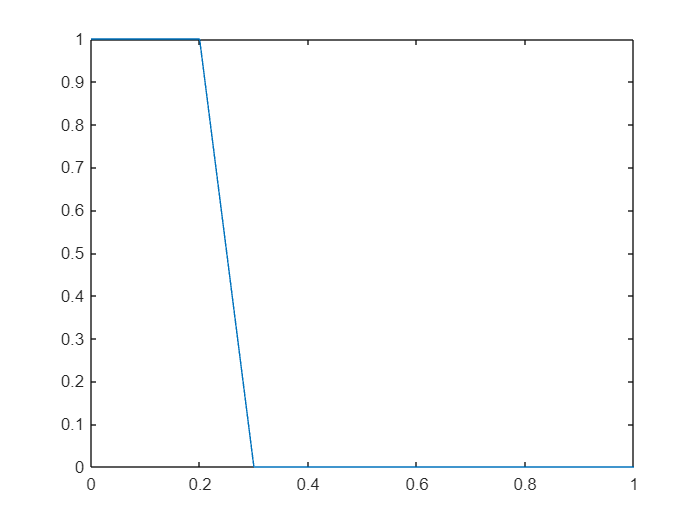

T_amb = [valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb,valor_T_amb]';
Tp = valor_Tp*ones(size(t));
Ts_ref = 40;

%vqs = zeros(size(t));
% vqs = [vqs,t];
% T_amb = [T_amb,t];
% Tp = [Tp,t];

Creo datos

vqs = timeseries(vqs,t);
T_amb = timeseries(T_amb,t);
Tp = timeseries(Tp,t);

Creo señales para el bus

% busSignal.busElement_1 = timeseries(vqs,t);
% busSignal.busElement_2 = timeseries(T_amb,t);
% busSignal.busElement_3 = timeseries(Tp,t);

% busInfo = Simulink.Bus.createObject(busSignal);

## Guardado de INPUTS

% ruta = 'C:\Users\tobip\Documents\Ayme\Matlab\inputs.mat';
% save(ruta, 'vqs');
% disp('Datos guardados correctamente')
disp('Datos guardados correctamente')

Datos guardados correctamente
